% read image and add the mask
img = double(imread('moon.tif'))/255;
img = img(141:140+256, 51:50+256);
msk = zeros(size(img));
msk(65:192,65:192) = imresize(imread('text.png'), 0.5);
img_corrupted = img;
img_corrupted(msk > 0) = nan;

fprintf(1, '%d corrupted entries\n', nnz(isnan(img_corrupted)));

1138 corrupted entries



% create a matrix X from overlapping patches
ws = 16; % window size
no_patches = size(img, 1) / ws;
X = zeros(no_patches^2, ws^2);
k = 1;
for i = (1:no_patches*2-1)
    for j = (1:no_patches*2-1)
        r1 = 1+(i-1)*ws/2:(i+1)*ws/2;
        r2 = 1+(j-1)*ws/2:(j+1)*ws/2;
        patch = img_corrupted(r1, r2);
        X(k,:) = patch(:);
        k = k + 1;
    end
end

% apply Robust PCA
lambda = 0.02; % close to the default one, but works better
tic
[L, S] = RobustPCA(X, lambda, 1.0, 1e-5);

iter: 0001	err: 0.019728	rank(L): 116	card(S): 36781
iter: 0010	err: 0.002855	rank(L): 24	card(S): 179010
iter: 0020	err: 0.001465	rank(L): 25	card(S): 201541
iter: 0030	err: 0.000628	rank(L): 27	card(S): 210094
iter: 0040	err: 0.000327	rank(L): 27	card(S): 214691
iter: 0050	err: 0.000207	rank(L): 27	card(S): 217504
iter: 0060	err: 0.000144	rank(L): 27	card(S): 219433
iter: 0070	err: 0.000119	rank(L): 27	card(S): 220683
iter: 0080	err: 0.000085	rank(L): 28	card(S): 221596
iter: 0090	err: 0.000069	rank(L): 28	card(S): 222344
iter: 0100	err: 0.000057	rank(L): 28	card(S): 222923
iter: 0110	err: 0.000046	rank(L): 28	card(S): 223424
iter: 0120	err: 0.000041	rank(L): 28	card(S): 223805
iter: 0130	err: 0.000036	rank(L): 28	card(S): 224136
iter: 0140	err: 0.000030	rank(L): 28	card(S): 224434
iter: 0150	err: 0.000026	rank(L): 28	card(S): 224686
iter: 0160	err: 0.000023	rank(L): 28	card(S): 224903
iter: 0170	err: 0.000020	rank(L): 28	card(S): 225105
iter: 0180	err: 0.000018	rank(L): 28	card(S): 

toc

Elapsed time is 6.297093 seconds.


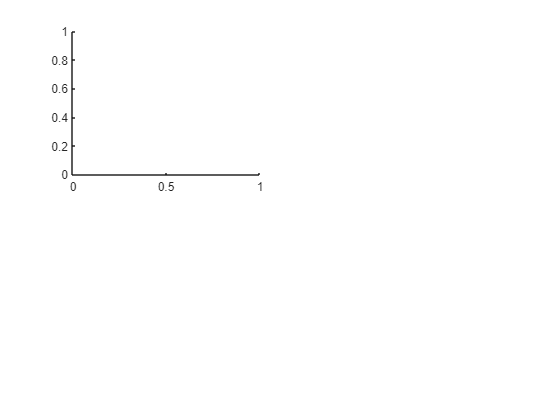

Execution of script image as a function is not supported:
C:\Users\aks19\OneDrive\SEM4\MIS4\project\image.mlx

Error in images.internal.basicImageDisplay (line 24)
    hh = image(cdata, ...

Error in imshow (line 330)
hh = images.internal.basicImageDisplay(fig_handle,ax_handle,...


% reconstruct the image from the overlapping patches in matrix L
img_reconstructed = zeros(size(img));
img_noise = zeros(size(img));
k = 1;
for i = (1:no_patches*2-1)
    for j = (1:no_patches*2-1)
        % average patches to get the image back from L and S
        % todo: in the borders less than 4 patches are averaged
        patch = reshape(L(k,:), ws, ws);
        r1 = 1+(i-1)*ws/2:(i+1)*ws/2;
        r2 = 1+(j-1)*ws/2:(j+1)*ws/2;
        img_reconstructed(r1, r2) = img_reconstructed(r1, r2) + 0.25*patch;
        patch = reshape(S(k,:), ws, ws);
        img_noise(r1, r2) = img_noise(r1, r2) + 0.25*patch;
        k = k + 1;
    end
end
img_final = img_reconstructed;
img_final(~isnan(img_corrupted)) = img_corrupted(~isnan(img_corrupted));

% show the results
figure;
subplot(2,2,1), imshow(img_corrupted), title('Corrupted image')

subplot(2,2,2), imshow(img_final), title('Recovered image')
subplot(2,2,3), imshow(img_reconstructed), title('Recovered low-rank')
subplot(2,2,4), imshow(img_noise), title('Recovered sparse')

fprintf(1, 'ws=%d\tlambda=%f\trank(L)=%d\tcard(S)=%d\terr=%f\n', ...
       ws, lambda, rank(L), nnz(S), norm(img - img_final, 'fro'));


function [L, S] = RobustPCA(X, lambda, mu, tol, max_iter)
    % - X is a data matrix (of the size N x M) to be decomposed
    %   X can also contain NaN's for unobserved values
    % - lambda - regularization parameter, default = 1/sqrt(max(N,M))
    % - mu - the augmented lagrangian parameter, default = 10*lambda
    % - tol - reconstruction error tolerance, default = 1e-6
    % - max_iter - maximum number of iterations, default = 1000

    [M, N] = size(X);
    unobserved = isnan(X);
    X(unobserved) = 0;
    normX = norm(X, 'fro');

    % default arguments
    if nargin < 2
        lambda = 1 / sqrt(max(M,N));
    end
    if nargin < 3
        mu = 10*lambda;
    end
    if nargin < 4
        tol = 1e-6;
    end
    if nargin < 5
        max_iter = 1000;
    end
    
    % initial solution
    L = zeros(M, N);
    S = zeros(M, N);
    Y = zeros(M, N);
    
    for iter = (1:max_iter)
        % ADMM step: update L and S
        L = Do(1/mu, X - S + (1/mu)*Y);
        S = So(lambda/mu, X - L + (1/mu)*Y);
        % and augmented lagrangian multiplier
        Z = X - L - S;
        Z(unobserved) = 0; % skip missing values
        Y = Y + mu*Z;
        
        err = norm(Z, 'fro') / normX;
        if (iter == 1) || (mod(iter, 10) == 0) || (err < tol)
            fprintf(1, 'iter: %04d\terr: %f\trank(L): %d\tcard(S): %d\n', ...
                    iter, err, rank(L), nnz(S(~unobserved)));
        end
        if (err < tol) break; end
    end
end

function r = So(tau, X)
    % shrinkage operator
    r = sign(X) .* max(abs(X) - tau, 0);
end

function r = Do(tau, X)
    % shrinkage operator for singular values
    [U, S, V] = svd(X, 'econ');
    r = U*So(tau, S)*V';
end